1. Find an interpolating polynomial using matrices to determine y at x = 3. Try linear, quadratic, and cubic polynomials between appropriate data points first, then try a polynomial that interpolates the entire data set. Make one plot with the data along with the 4 interpolating polynomials, then another plot with degree of interpolating polynomial on the horizontal axis and the estimated value of y at x = 3 on the vertical axis.

% linear polynomials
format long;
x = [0 1.8 5 6 8.2 9.2 12]';
y = [26 16.415 5.375 3.5 2.015 2.54 8]';

close all
plot(x, y, 'o');
hold on

x1 = [1.8 5]';
y1 = [16.415 5.375]';
x2 = [1.8 5 6]';
y2 = [16.415 5.375 3.5]';
x3 = [0 1.8 5 6]';
y3 = [26 16.415 5.375 3.5]';

%%%%% all of below actually we can just use polyfit to find the interpulation
usepolyfit = polyfit(x1, y1, 1);
disp(usepolyfit);

  -3.450000000000001  22.625000000000004




% t = [300 400 500]';
% p = [0.616 0.525 0.457]';
al = poly_interp(x1, y1);
aq = poly_interp(x2, y2);
ac = poly_interp(x3, y3);
disp(al);

  -3.450000000000000
  22.625000000000000



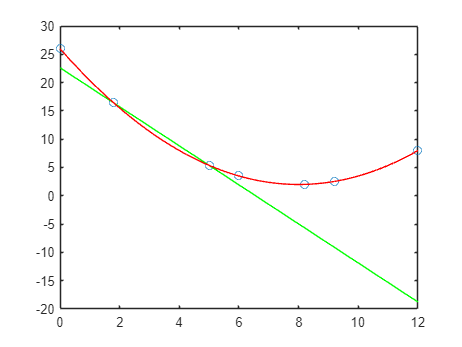


linear = @(x) al(1)*x + al(2);
quad = @(x) aq(1)*x.^2 + aq(2)*x + aq(3);
cub = @(x) ac(1)*x.^3 + ac(2)*x.^2 + ac(3)*x + ac(4);

X = linspace(0, 12);
plot(X, linear(X), 'g');
plot(X, quad(X), 'b');
plot(X, cub(X), 'r');
hold off


disp(quad(3));

  11.374999999999996



disp(cub(3));

  11.374999999999996



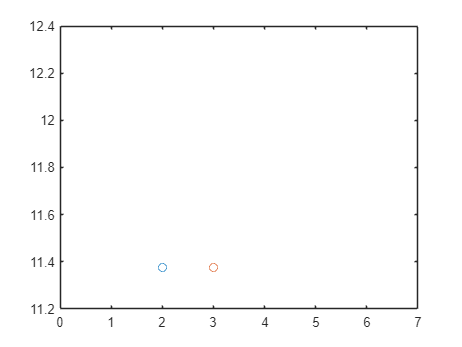

plot(2, quad(3), 'o');
xlim([0, 7]);
ylim([11.2, 12.4]);
hold on
plot(3, cub(3), 'o');
hold off

4. Use any built-in Matlab functions to do inverse interpolation to estimate the value of x at which f(x) = 1.7.

% Given data
x = [1 2 3 4 5 6 7];
y = [3.6 1.8 1.2 0.9 0.72 1.5 0.51429];
n = length(x);
desired_value = 1.7;

p = polyfit(x, y, n-1)

p =   -0.006785708333335   0.144999875000036  -1.194998958333656   4.749995625001428  -9.032490333336556   5.904989500003442   3.034289999998670


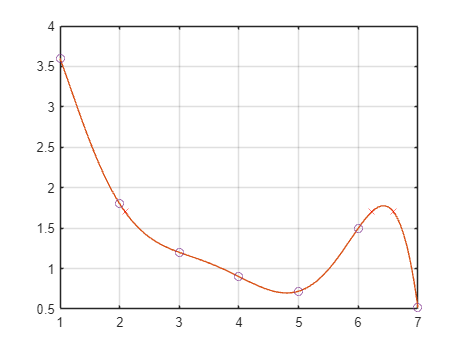


xx = linspace(1, 7);
yy = polyval(p, xx);

% Step 2: Plot
plot(xx, yy);
hold on
grid on

% Step 3: Root finding | Inverse Interpolation
y_question = 1.7;
root = roots([p(1) p(2) p(3) p(4) p(5) p(6) p(7)-y_question]);
root = root(imag(root) == 0);

func = @(x) p(1).*x.^6 + p(2).*x.^5 + p(3).*x.^4 + p(4).*x.^3 + p(5).*x.^2 + p(6).*x + p(7);

plot(root, func(root), 'xr');
scatter(x, y);
xlim([1, 7]);



% % x = [1 2 3 4 5 6 7];
% % y = [1 0.5 0.3333 0.25 0.2 0.1667 0.1429];
% x1 = [2 3 4];
% y1 = [0.5 0.3333 0.25];
% 
% a = polyfit(x1, y1, 2);
% disp(a);
% a1 = a(1);
% a2 = a(2);
% a3 = a(3);
% 
% % first try
% syms c
% % fx = @(x) a1*x.^2 + a2*x + a3;
% fx = a1*c.^2 + a2*c + a3 == 0.3;
% 
% sol = solve(fx, c);
% disp(double(sol))
% 
% % second try
% fx_input = 0.3;
% 
% delta = a2^2 - 4*a1*(a3 - fx_input);
% 
% if delta >= 0
%     x1 = (-a2 + sqrt(delta)) / (2*a1);
%     x2 = (-a2 - sqrt(delta)) / (2*a1);
%     disp(['Possible values of x: ', num2str(x1), ', ', num2str(x2)]);
% else
%     disp('No real solutions for x.');
% end

5. Use the portion of the given steam table for superheated water at 200 MPa to find: 

(a) the corresponding -entropy s for a specific volume υ of 0.118 with linear interpolation, 

(b) the same corresponding entropy using quadratic interpolation, and 

(c) the volume corresponding to an entropy of 6.45 using inverse interpolation of both the linear and quadratic cases

% question a
ax = [0.1114 0.12547];
ay = [6.5453 6.7664];
Aa = polyfit(ax, ay, 1);
a_function = @(x) Aa(1)*x + Aa(2);
%%% or u can do like this: bb = polyval(Aa, 0.118)

bb =    6.649014285714283


disp(a_function(0.118));

   6.649014285714283




% question b
bx = [0.10377 0.1114 0.12547];
by = [6.4147 6.5453 6.7664];
Ab = polyfit(bx, by, 2);
b_function = @(x) Ab(1)*x.^2 + Ab(2)*x + Ab(3);
disp(b_function(0.118));

   6.652200419759499




% question c
syms x
linear_func = Aa(1)*x + Aa(2) == 6.45;
quad_func = Ab(1)*x.^2 + Ab(2)*x + Ab(3) == 6.45;
sol_linear = solve(linear_func, x);
sol_quad = solve(quad_func, x);
disp(double(sol_linear));

   0.105335454545455



disp(double(sol_quad));

   0.105789540933507
   0.374242141309475



%%%% in number 5 you can do as the same as P'Champ do

6. . Sample the function, f = 1 / (1 + 25x2 ), 10 times equally spaced from -1 to 1 and store the results as data y, with x being the sample points. Use Matlab’s spline function to fit a curve to this data (note that Newton and Lagrange polynomials do not work for this). The blue curve is the correct one with splines. I also plotted the incorrect polyfit function in orange for comparison.

x = linspace(-1, 1, 10);
y = 1./(1+(25*x.^2));

xfit = linspace(-1, 1);
yfit = spline(x, y, xfit);
close all
plot(x,y,'or','MarkerSize',6);
hold on
plot(xfit, yfit);

7. Interpolate the following data using cubic splines with knot-a-not end condition and also with clamped end condition with first derivatives set equal to 0. Plot both curves along with the data on the same graph. Use both interpolating methods to estimate the y-value when x = 1.5.

x = [0 2 4 7 10 12];
y = [20 20 12 7 6 6];

xfit = linspace(0, 12);
ynot_fit = spline(x, y, xfit);
yclamp_fit = spline(x, [0 y 0], xfit);
ynot_fit_val = spline(x, y, 1.5);
yclamp_fit_val = spline(x, [0 y 0], 1.5); % still don't understand how to find the end condition of [0 y 0}
disp(ynot_fit_val);
disp(yclamp_fit_val);

close all
plot(x,y,'or','MarkerSize',6);
hold on
plot(xfit, ynot_fit, 'b');
plot(xfit, yclamp_fit, 'r');

8. The following grid represents 6 pixels of an image and their corresponding colour value (one of RGB for example).We zoom in and create more pixels which we need to interpolate in order to smooth out the image Use linear interpolation to find the missing values (store the values as a matrix containing the colour value at each of the coordinate locations).

format long
% x = [1 4];
% y = [10 15];
% x = [4 7];
% y = [15 30]
x = [1 4];
y = [10 30];
a = polyfit(x, y, 1);
Y = polyval(a, 3);
disp(Y)

  23.333333333333332




% yfit = spline(x, y, 2);
% disp(yfit);

function U = poly_interp(x, y)
A = [];
n = length(x);
B = y;
for i = 1:n
    for j = 1:n
        A(i,j) = x(i)^(j-1);
    end
end
U = flip(A\B);
end